# Taller 2: Frequency Design 

## Magistral Control

#### Eduardo Toro Bernal 

#### Ingeniería Electrónica

#### Universidad Nacional de Colombia 

## Ejercicio 1: 

La función de transferencia de lazo abierto de un sistema con realimentación unitaria es: 


$$G(s) = \frac{K}{s(s/5 + 1)(s/50 +1) }$$


Diseñar un compensador de atraso para G(s) usando los diagramas de BODE para que el sistema de lazo cerrado cumpla con las siguientes especificaciones: 

- El error de estado estacionario para una entrada rampa unitaria de referencia es menor que 0.01. 

- PM $\ge 40\degree$

### Solución: 

Como la planta es de  tipo 1, no necesitamos añadir (además de la red) un controlador ya que obtendriamos un valor de error finito. Sin embargo, debemos hallar el valor de K que haga que dicho valor finito sea menor a la condición dada: 

$e_v = |\frac{1}{k_v}|$ donde $k_{v\;} =\lim_{s\to 0} \;\;\;\;s*G\left(s\right)*C_0 \left(s\right)$

Teniendo en cuenta que la red de atraso no influye en el error, reemplazamos: 


$$k_v = lim_{s->0}  \frac{K*s}{s(s/5 + 1)(s/50 +1) }$$
 

Al solucionar y reemplazar en la formula del error se obtiene: 


$$k_v =K$$
  

$e_v = |\frac{1}{K}|=0.01$  entonces $K>100$.

Por ende, seleccionamos: 

k1 = 150 

k1 = 150

La función de transferencia de lazo abierto descompuesta queda: 

s = tf('s');  
C1 = k1

C1 = 150

G1 = 1 / (s*(s/5 + 1)*(s/50 + 1))

G1 =
 
          250
  --------------------
  s^3 + 55 s^2 + 250 s
 
Continuous-time transfer function.



Ploteamos su BODE para observar los margenes actuales: 

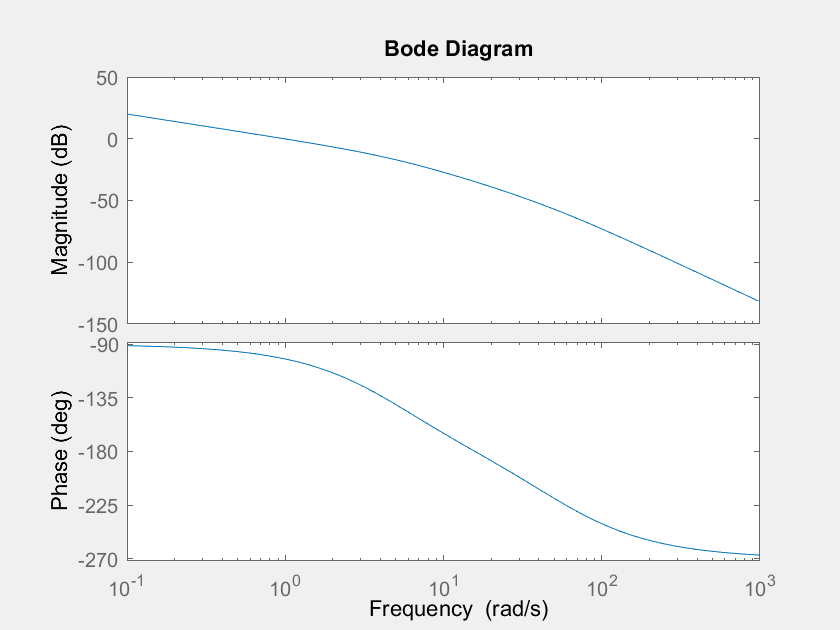

figure("Name", 'FT de lazo abierto Ejemplo 1'); 
set(gcf,'Visible', 'on');
bode(G1)

Se observa que tiene margen de fase igual a 77.8° y además nos muestra que el sistema en lazo cerrado será estable: 

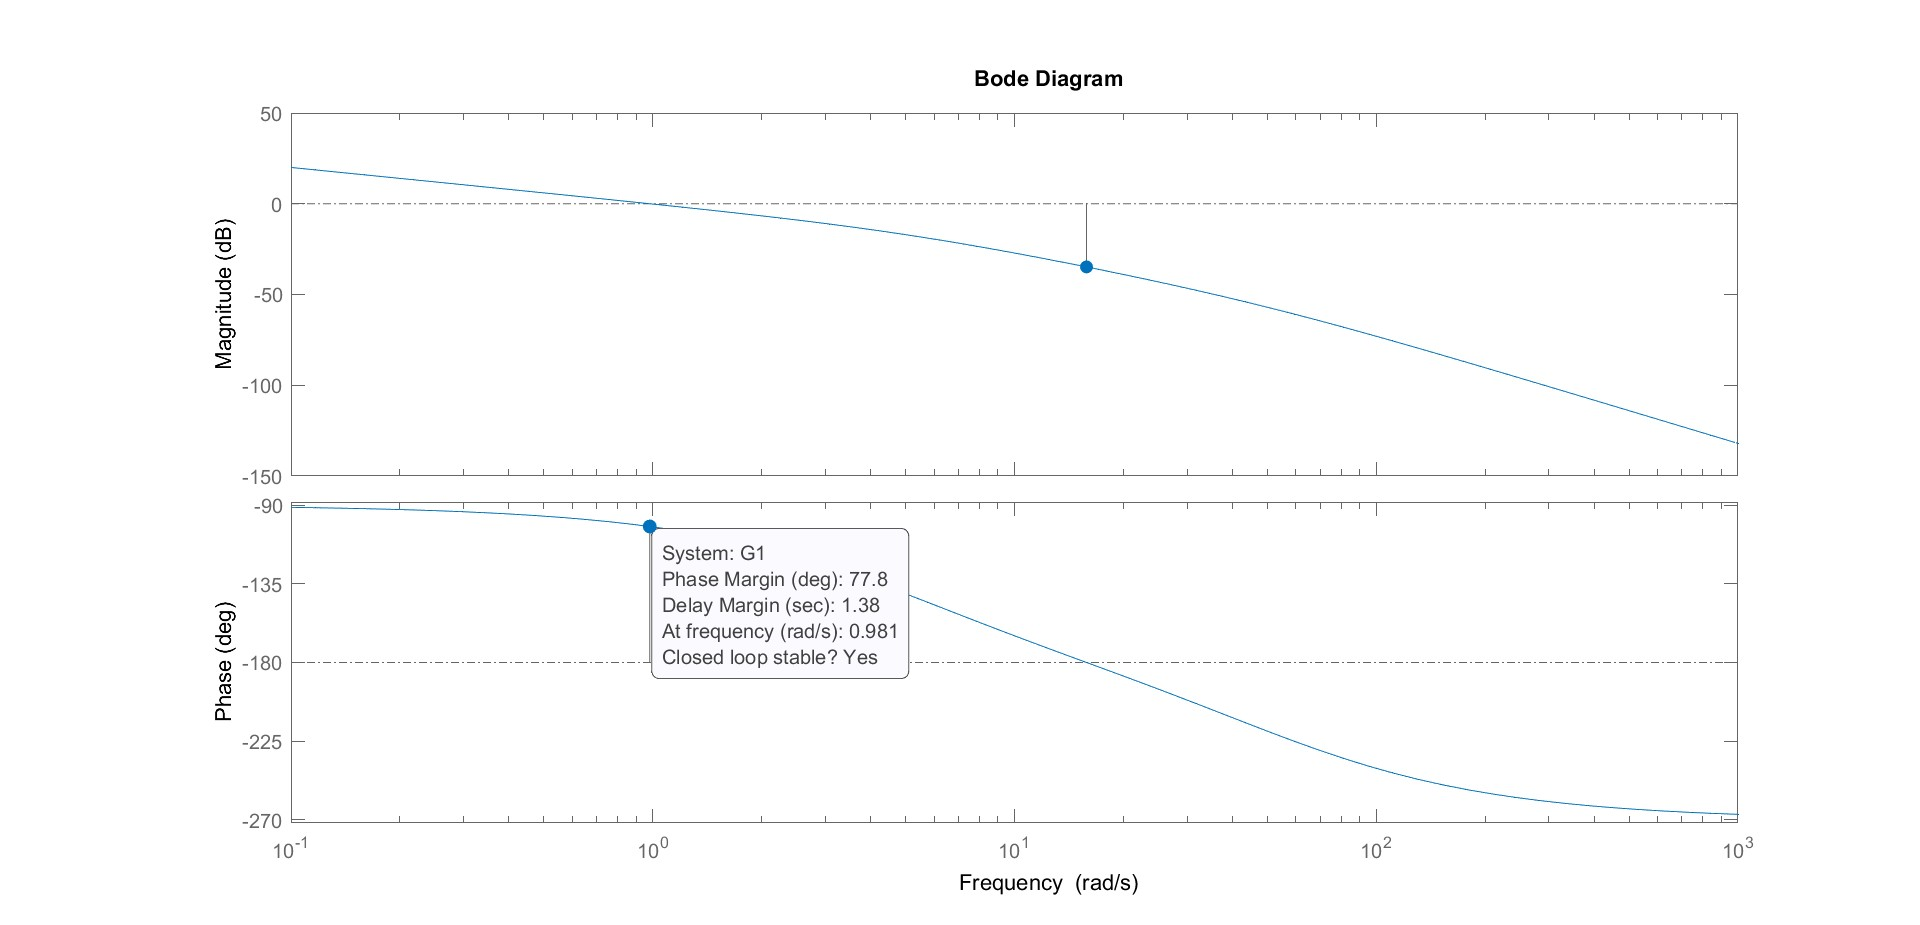

Empezamos el diseño de la red de atraso: 

phase1 = -180 + 40 + 6; 

Igualamos este resultado al angulo de la función de transferencia de lazo abierto para hallar la nueva frecuencia de ganancia: 

syms x; 
eqn1 = (-90 - atand(x/5) - atand(x/50)) == phase1; 
solution1 = solve(eqn1,x,'Real', true); 
display(solution1);

$$solution1 = \frac{55\,\left(\sqrt{\frac{40\,{\tan\left(\frac{11\,\pi }{45}\right)}^{2}}{121}+1}-1\right)}{2\,\tan\left(\frac{11\,\pi }{45}\right)}$$

wg1 = vpa(solution1);
wg1 = double(wg1)

wg1 = 4.0951

Ahora calculamos la distancia que genera la nueva frecuencia de ganancia: 

d1 = (k1/(wg1*sqrt((wg1/5)^2+1)*sqrt((wg1/50)^2+1)));
d1 = double(d1)

d1 = 28.2436

Con este resultado podemos hallar el valor del parámetro "a" de la red de atraso: 

a1 = 1/d1;
a1 = double(a1)

a1 = 0.0354

Tomamos el punto de ingreso a la red una decada más arriba del cero: 

T1 = 10 /(a1*wg1);
T1 = double(T1)

T1 = 68.9700

Por ende, la red de atraso queda definida de la forma: 

C_atraso1 = (1+(a1*T1*s))/(1+T1*s)

C_atraso1 =
 
  2.442 s + 1
  -----------
  68.97 s + 1
 
Continuous-time transfer function.



Ahora comprobamos los resultados obtenidos: 

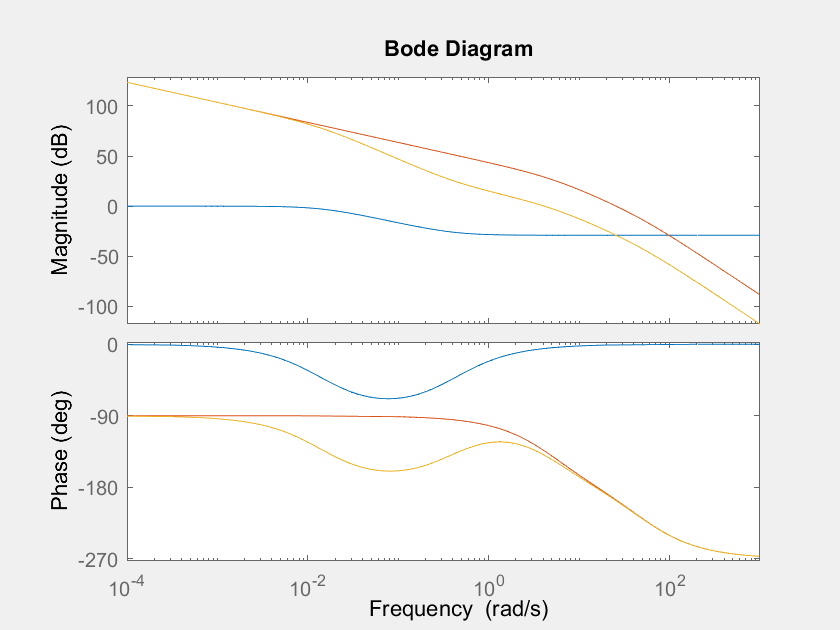

figure("Name", 'Sistema con red de atraso Ejercicio 1'); 
set(gcf,'Visible', 'on');
bode(C_atraso1); 
hold on
bode(G1*C1); 
bode(C1*G1*C_atraso1); 
hold off

Como se puede observar el criterio de margen de fase se cumple ya que se obtiene $M_p =40\ldotp 4\degree$

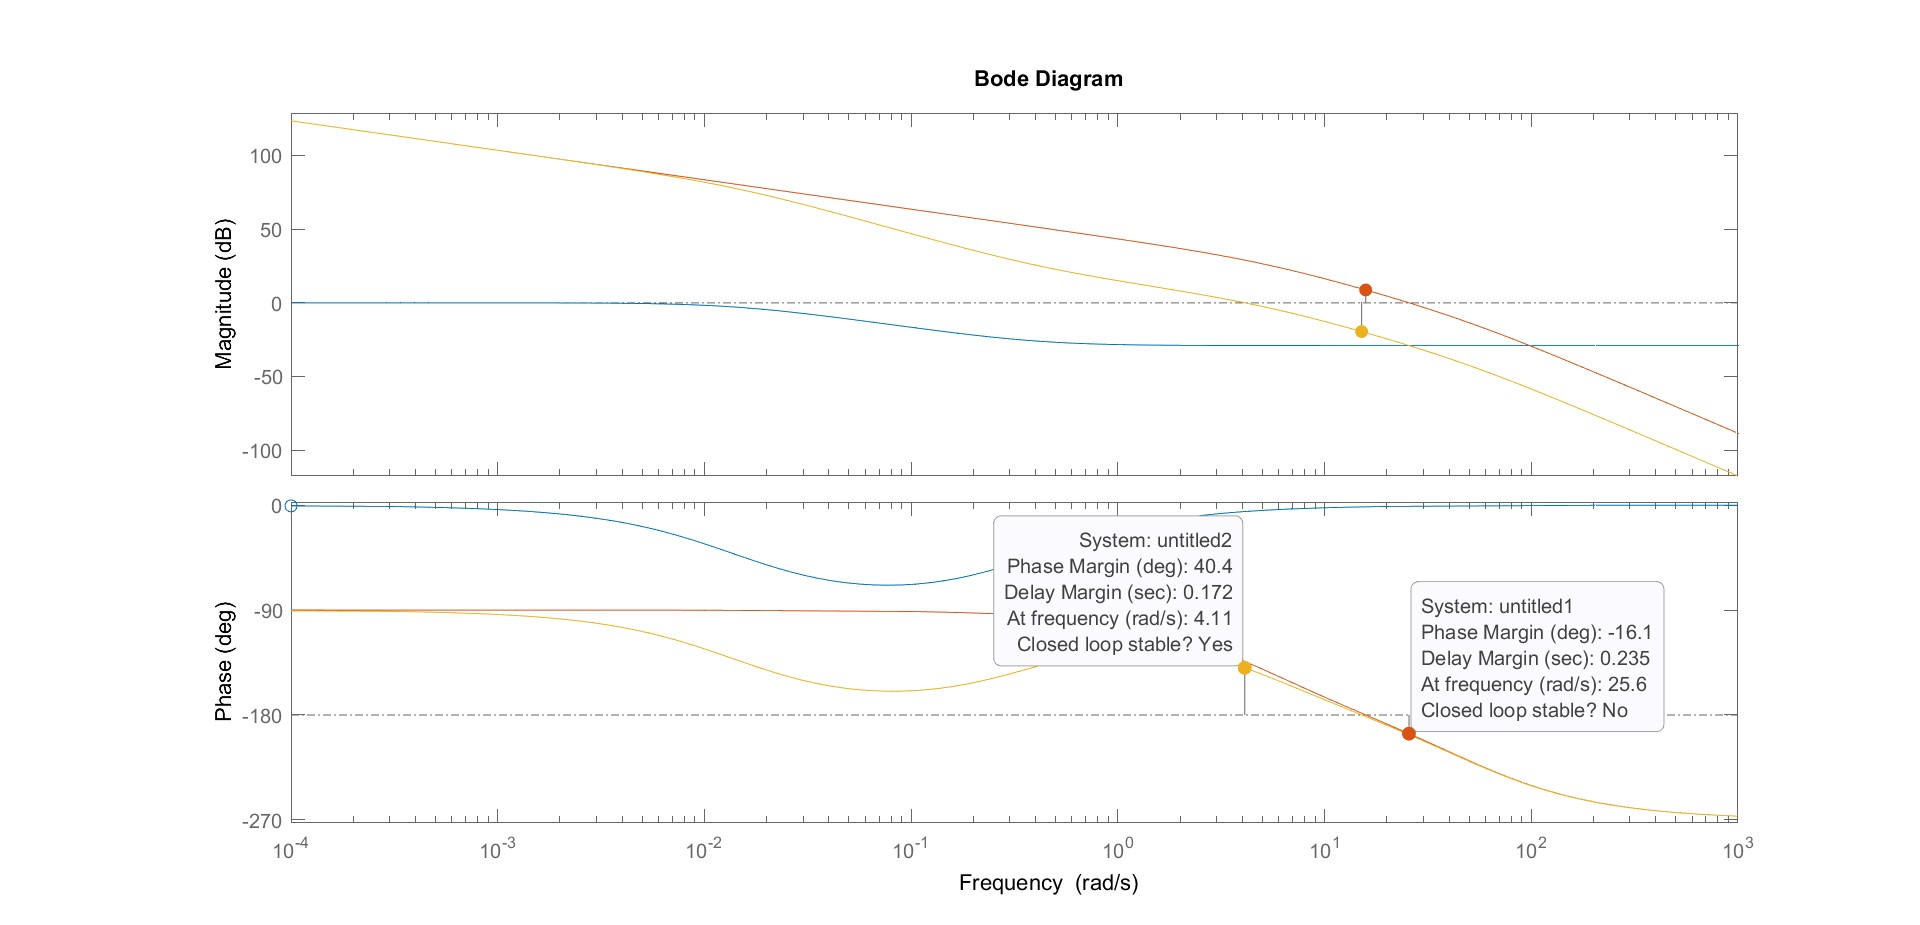

Por otro lado, realizamos el lazo cerrado del sistema con el fin de analizar su respuesta ante una entrada determinada: 

G01 = feedback(C1*G1*C_atraso1,1)

G01 =
 
                    9.157e04 s + 37500
  -------------------------------------------------------
  68.97 s^4 + 3794 s^3 + 1.73e04 s^2 + 9.182e04 s + 37500
 
Continuous-time transfer function.



Observamos la respuesta al paso: 

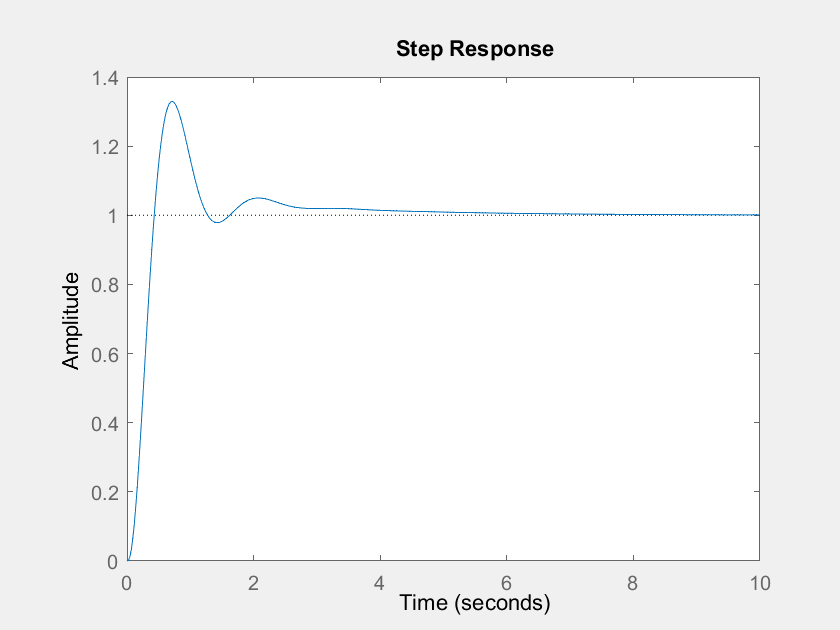

figure("Name", 'Respuesta Ante un Paso');
set(gcf,'Visible', 'on');
step(G01); 

Observamos la respuesta ante una rampa: 

t1 = -5:0.01:30; 
ramp1 = ramp(t1); 
figure("Name", 'Respuesta Ante una Rampa');
set(gcf,'Visible', 'on');
response1 = lsim(G01, ramp1,t1); 

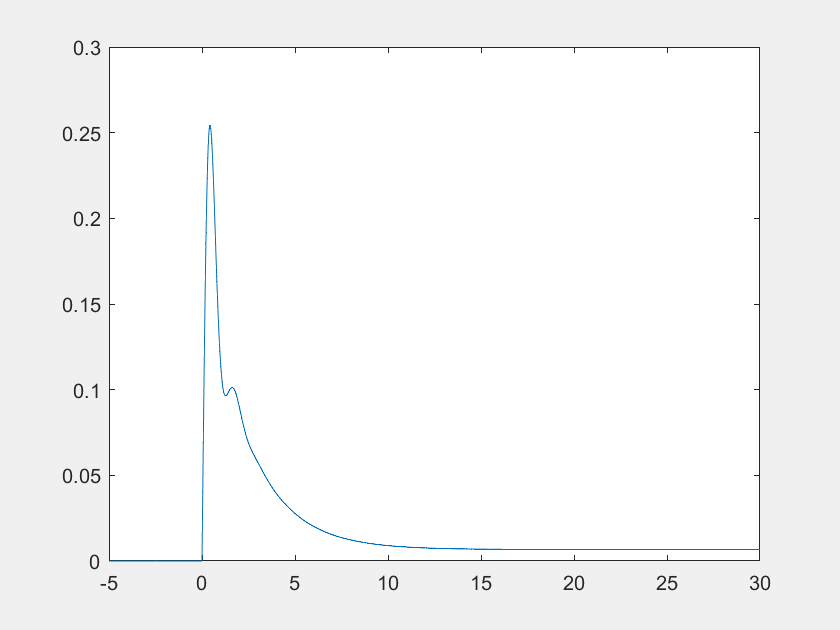

plot(t1, ramp1'-response1)

El criterio del error se cumple ya que la resta entre la rampa ideal y la obtenida por medio de simulación en el estado estacionario da un valor igual a 0.0066.

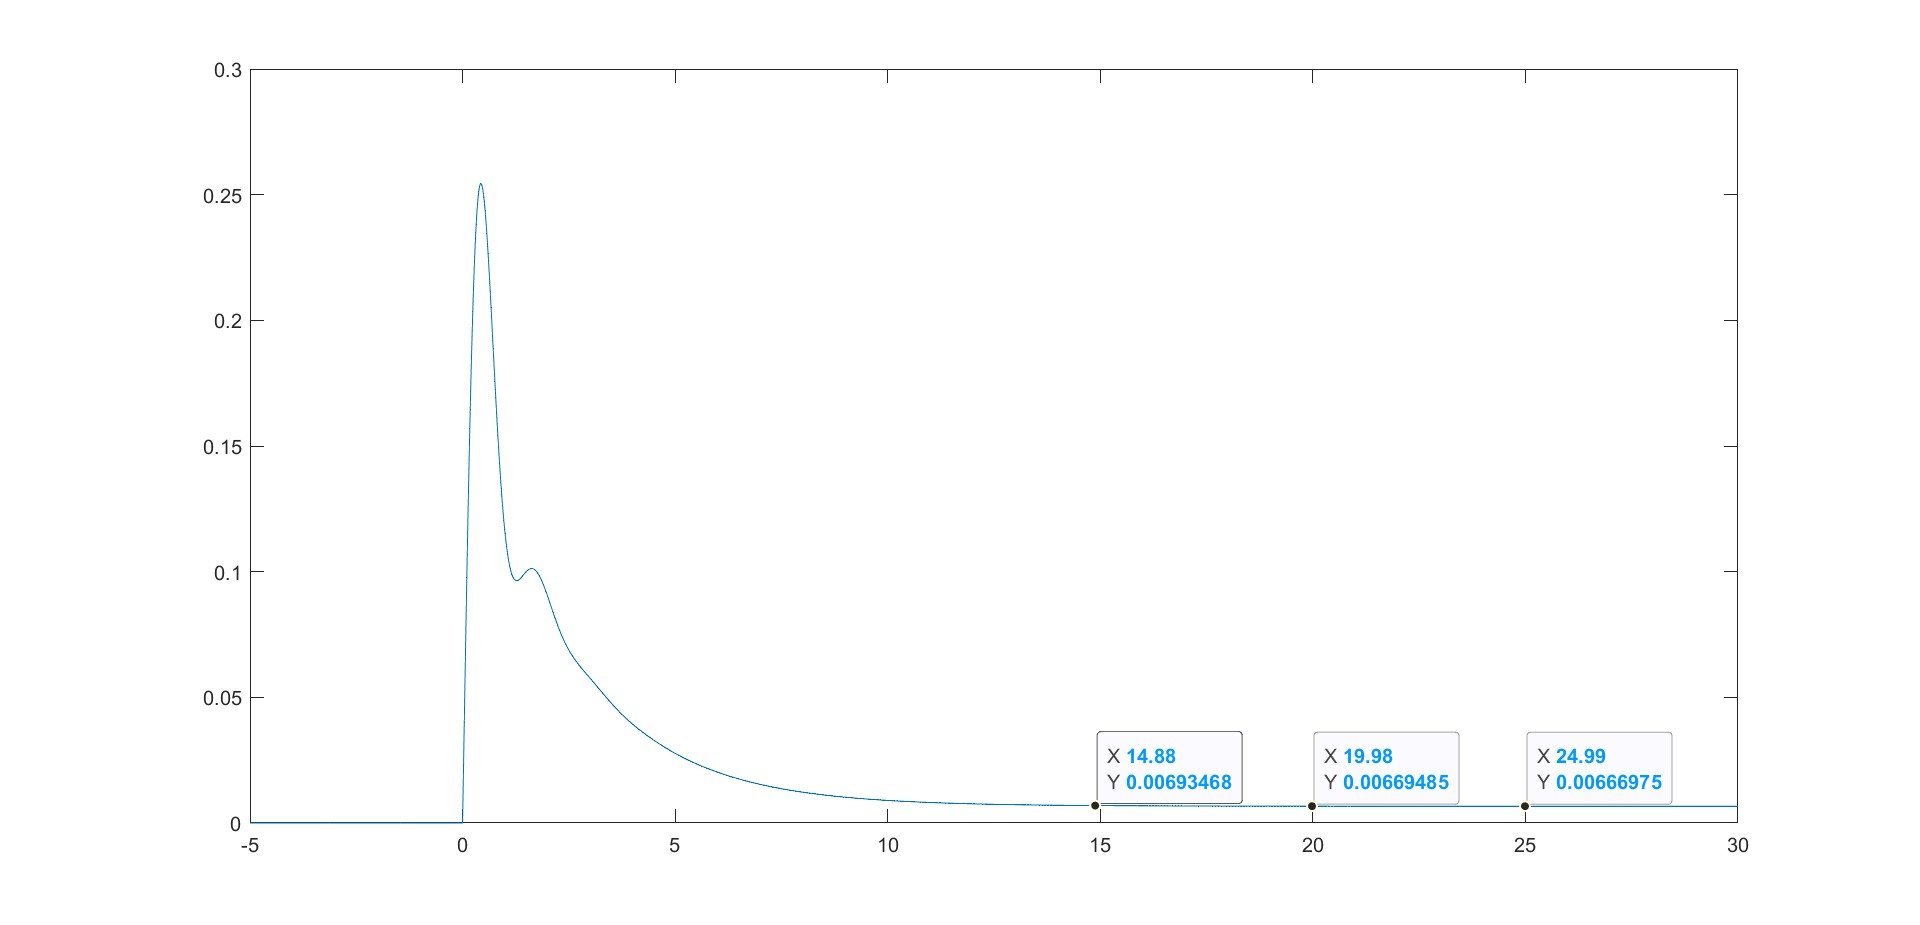

## Ejercicio 2: 

La función de transferencia de lazo abierto de un sistema de realimentación unitaria es: 


$$G\left(s\right)=\frac{K}{s\left(\frac{s}{5}+1\right)\left(\frac{s}{200}+1\right)}$$


Diseñar un compensador de adelanto para G(s) usando el diagrama de BODE para que el sistema de lazo cerrado cumpla con las siguientes condiciones: 

- El error de estado estable ante una entrada rampa de referencia unitaria es menor que 0.01. 

- Para los polos dominantes del sistema de lazo cerrado el factor de amortiguamiento es mayor o igual a 0.4. 

### Solución: 

Para cumplir con el criterio del error obtenemos el mismo resultado que en el ejercicio anterior ya que al aplicar el limite, el nuevo coeficiente de la planta no afecta el resultado, por ende, K>100. En este caso seleccionamos: 

k2 = 130; 

La función de transferencia de lazo abierto queda: 

s = tf('s');  
G2 = k2 / (s*(s/5 + 1)*(s/200 + 1))

G2 =
 
          130000
  ----------------------
  s^3 + 205 s^2 + 1000 s
 
Continuous-time transfer function.



Ploteamos su BODE para observar los margenes actuales: 

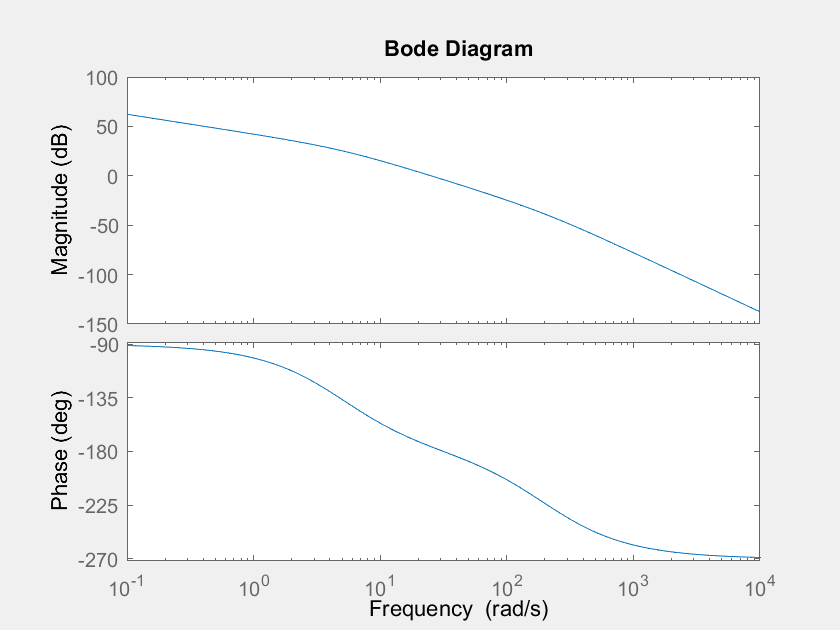

figure("Name", 'FT de lazo abierto Ejemplo 2'); 
set(gcf,'Visible', 'on');
bode(G2)

Se observa que tiene margen de fase igual a 2.78° y además nos muestra que el sistema en lazo cerrado será estable: 

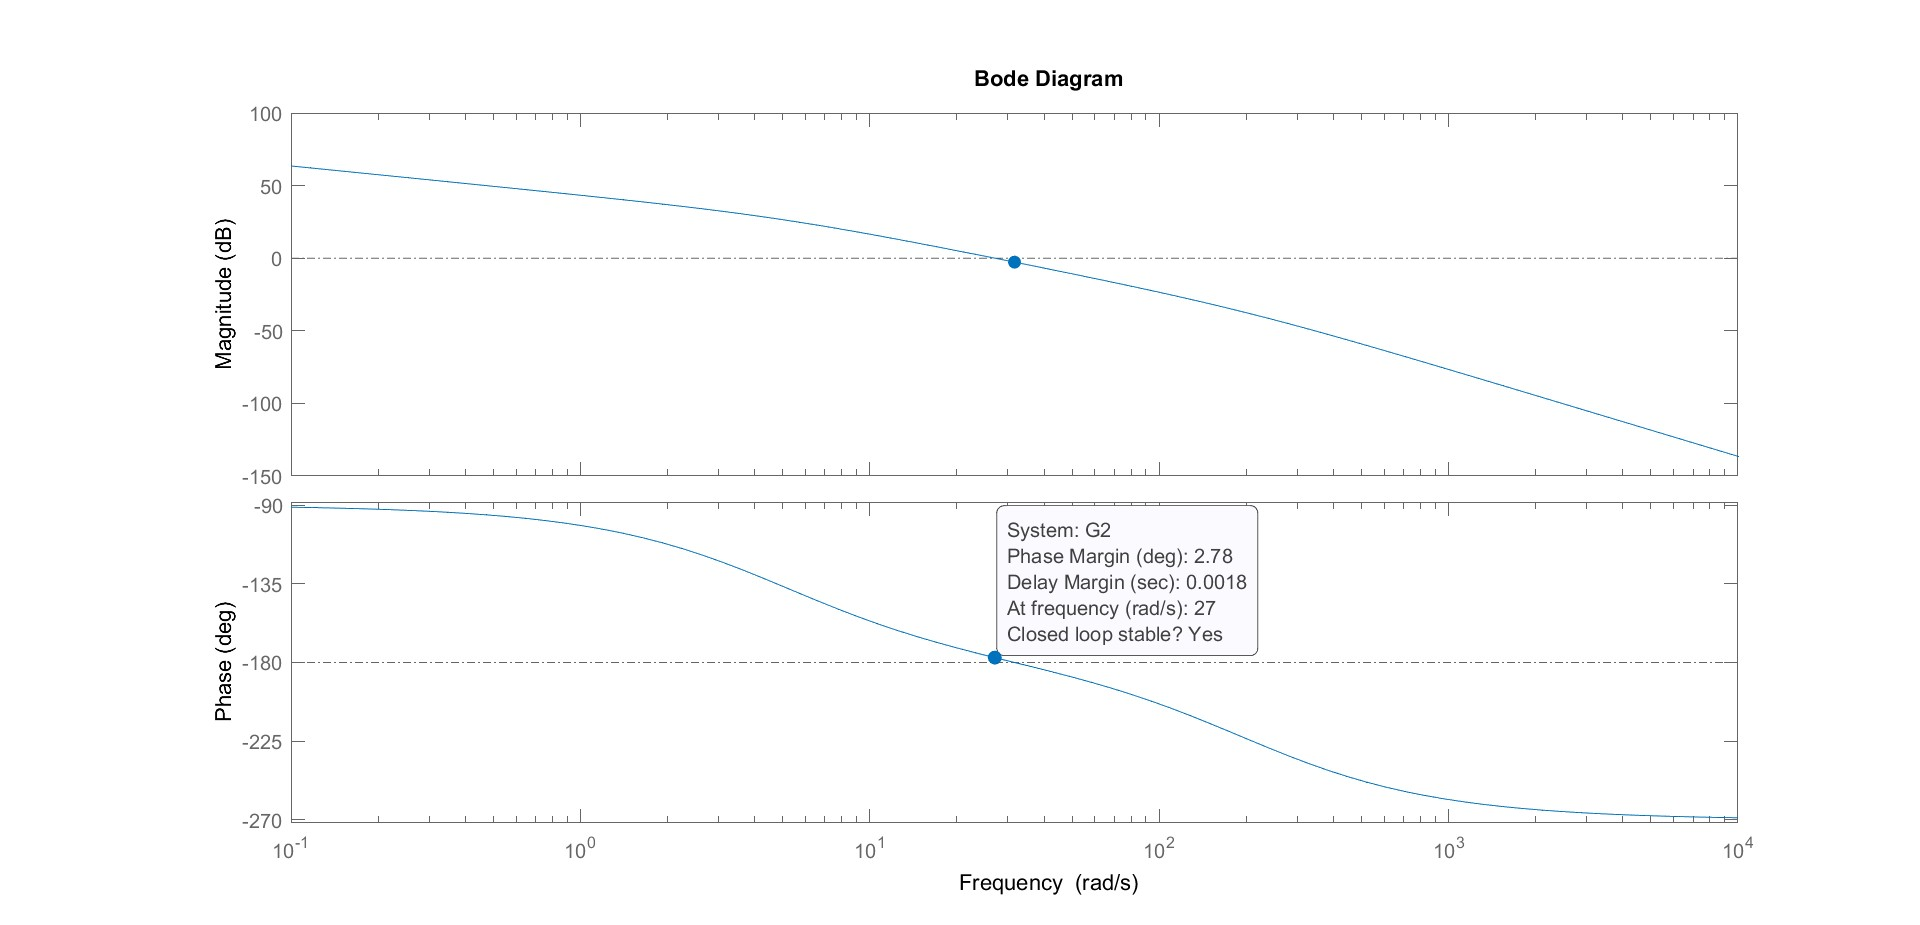

Empezamos con el diseño de la red de adelanto: 

campana2 = 60 - 2.78 + 20

campana2 = 77.2200

Calculamos el parámetro "b" de la red: 

b2 = (1+sind(campana2))/(1-sind(campana2))

b2 = 79.7319

Calculamos la amplificación que genera "b": 

syms x; 
eqn = (k2 / (x*sqrt((x/5)^2+1)*sqrt((x/200)^2+1))) == 10^((-10/20)*log10(b2)); 
solution = solve(eqn,x,'Real', true); 
display(solution);

$$solution = \frac{1}{\sqrt{\mathrm{root}\left(z^{3}-\frac{65121991446405138767919496801849\,z^{2}}{87749816909238586922165387963819622400}-\frac{104260308305694627167439114379760249\,z}{3509992676369543476886615518552784896000000}-\frac{65121991446405138767919496801849}{87749816909238586922165387963819622400000000},z,3\right)}}$$

wg2 = vpa(solution);
wg2 = double(wg2)

wg2 = 73.7119

Calculamos el punto donde vamos a insertar la campana: 

T2 = 1/(sqrt(b2)*wg2); 
T2 = double(T2)

T2 = 0.0015

La red de adelanto queda: 

C_adelanto2 = (1+(b2*T2*s))/(1+T2*s)

C_adelanto2 =
 
   0.1211 s + 1
  --------------
  0.001519 s + 1
 
Continuous-time transfer function.



Comprobamos los resultados obtenidos: 

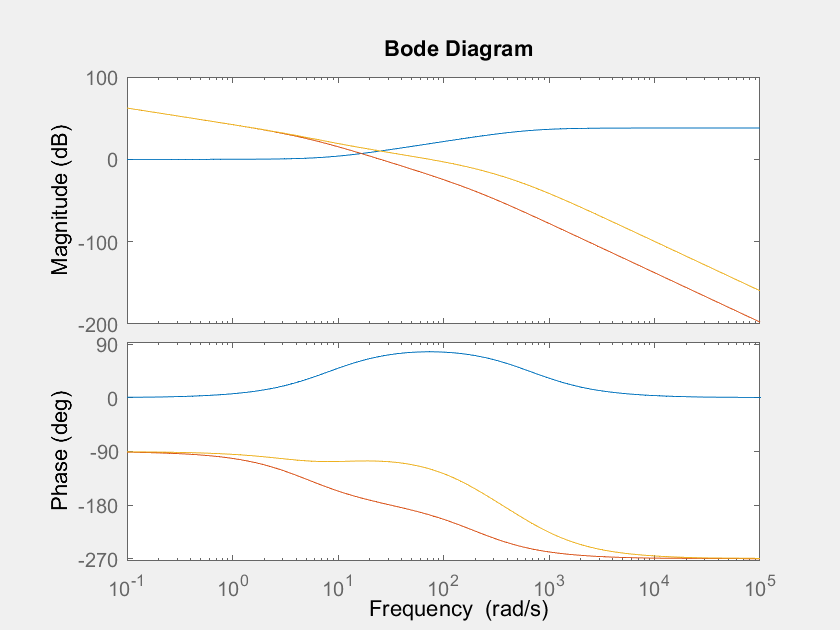

figure("Name", 'Sistema con red de adelanto Ejercicio 2'); 
set(gcf,'Visible', 'on');
bode(C_adelanto2); 
hold on
bode(G2); 
bode(G2*C_adelanto2); 
hold off

El sistema de lazo cerrado del sistema queda: 

G02 = feedback(G2*C_adelanto2,1); 

Observamos la respuesta al paso para saber el sobrepico que se genera:

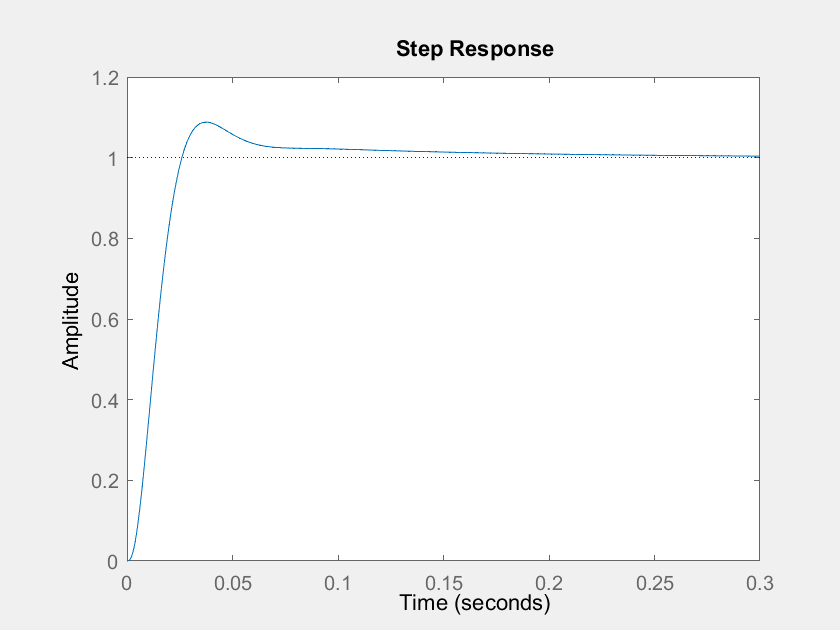

figure("Name", 'Respuesta Ante un Paso Ejercicio 2');
set(gcf,'Visible', 'on');
step(G02); 

damp(G02)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.63e+00                 1.00e+00       8.63e+00         1.16e-01    
 -8.29e+01 + 8.67e+01i     6.91e-01       1.20e+02         1.21e-02    
 -8.29e+01 - 8.67e+01i     6.91e-01       1.20e+02         1.21e-02    
 -6.89e+02                 1.00e+00       6.89e+02         1.45e-03    


El sobrepico obtenido es: 

Mp = 0.0881

Mp = 0.0881

Despejando el factor de amortiguamiento se tiene: 

zita = sqrt((log(Mp)^2)/(log(Mp)^2 + pi^2)); 
zita = double(zita)

zita = 0.6117

Para observar el criterio del error ante la respuesta al paso: 

t2 = -5:0.01:30; 
ramp2 = ramp(t2); 
figure("Name", 'Respuesta Ante una Rampa Ejercicio 2');
set(gcf,'Visible', 'on');
response2 = lsim(G02, ramp2,t2); 

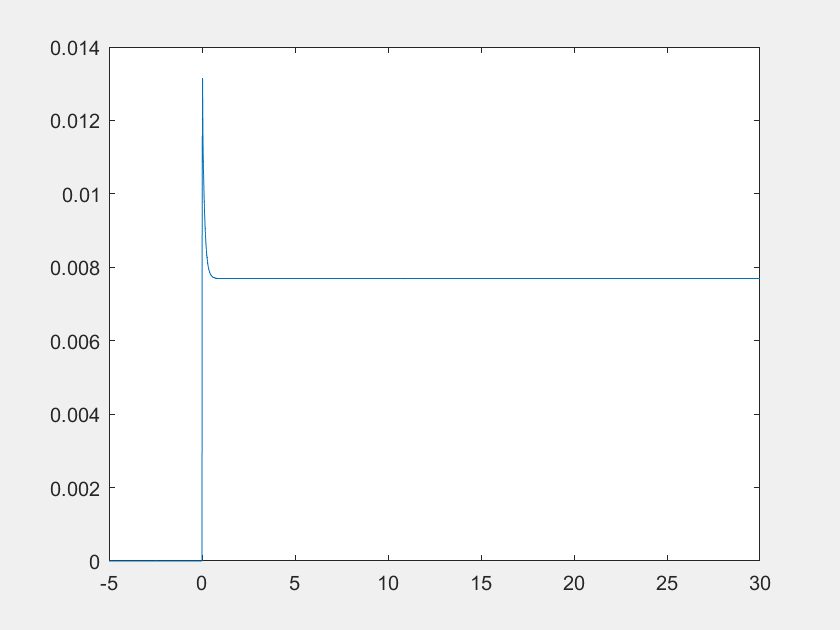

plot(t2, ramp2'-response2)

El criterio del error se cumple ya que la resta entre la rampa ideal y la obtenida por medio de simulación en el estado estacionario da un valor igual a 0.00769.

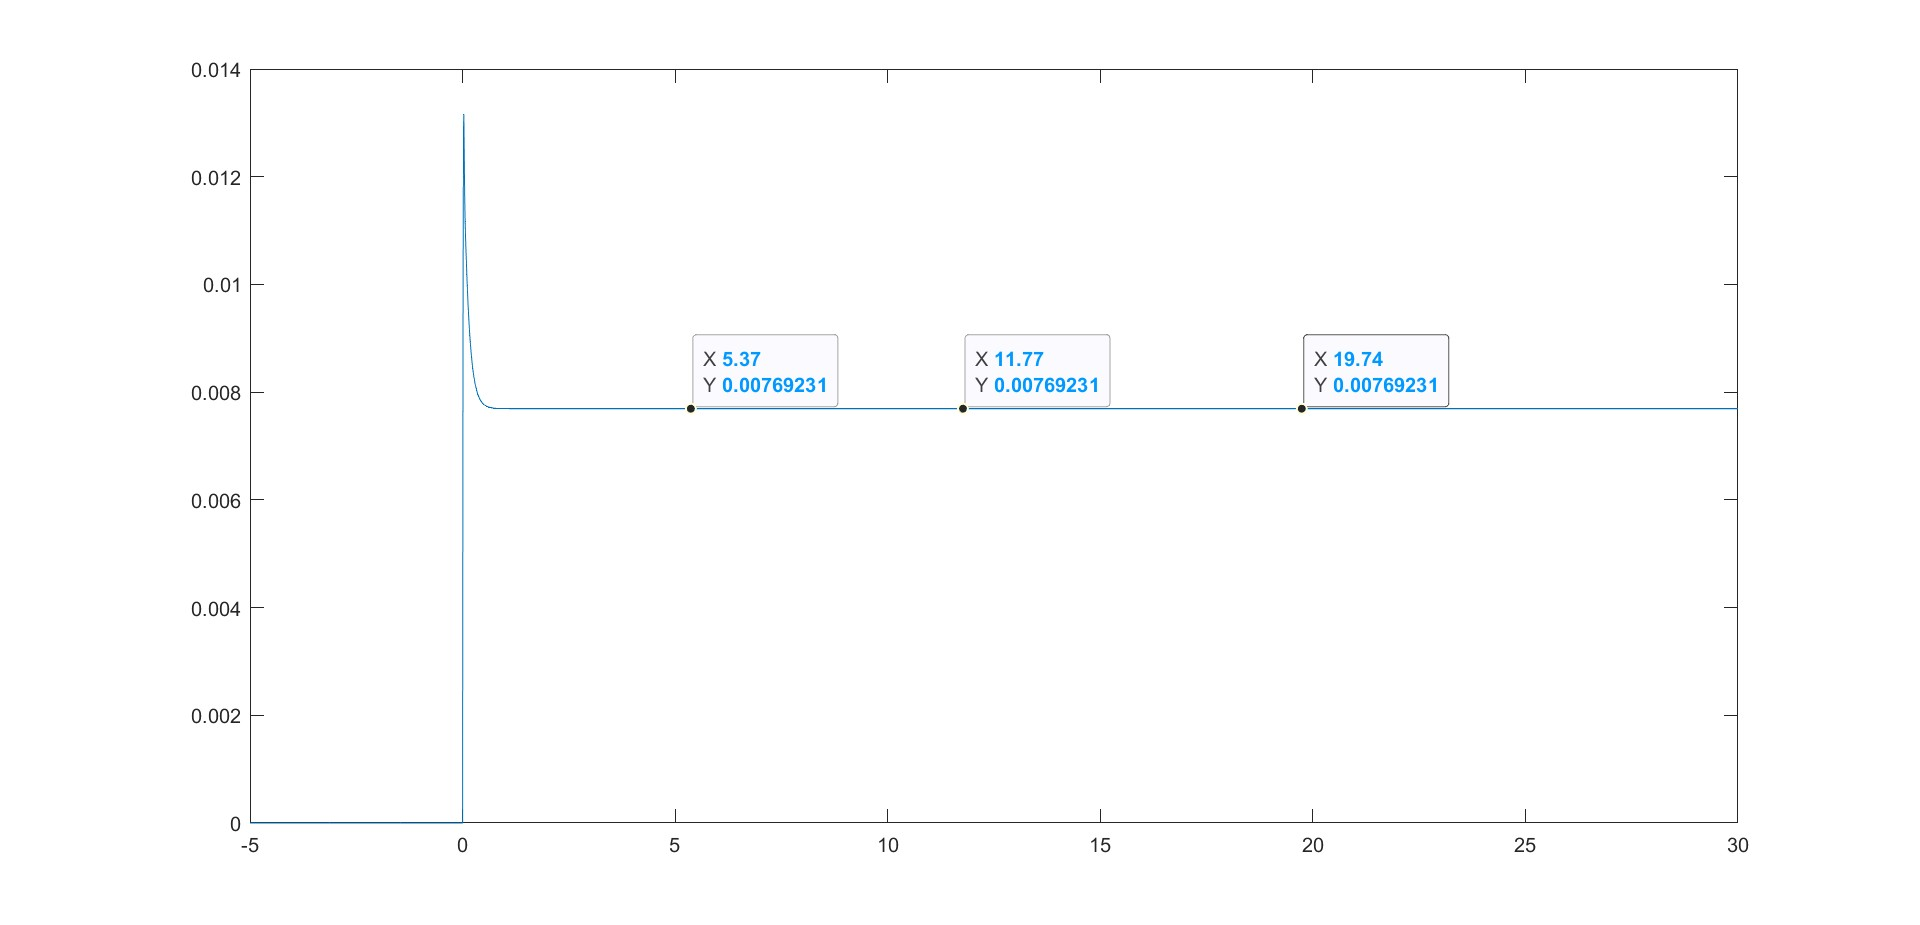 

## Ejercicio 3:

Se va a utilizar un motor DC con una inductancia de armadura despreciable en un sistema de control de posición. La función de transferencia de lazo abierto esta dada por: 


$$G\left(s\right)=\frac{50}{s\left(\frac{s}{5}+1\right)}$$
 

Diseñar un compensador para el motor usando los diagramas de BODE para que el sistema de lazo cerrado cumpla con las siguientes condiciones: 

- El error de estado estable ante una entrada unitaria tipo rampa es menor que 1/200 = 0.005. 

- La respuesta ante un paso unitario tiene un sobrepico menor que 20%.

- El ancho de banda del sistema compensado no es menor que el del sistema no compensado. 

### Soolución:

Partimos del criterio del error: 

$e_v =|\frac{1}{k_v }|$ donde $k_v =\lim_{s\to 0} \;\;\;s*k_p *$ $\frac{50}{s\left(\frac{s}{5}+1\right)}$=$\frac{k_p *50}{\left(\frac{s}{5}+1\right)}$

Aplicando el limite obtenemos: $k_v =k_p *50$

Con este valor hallamos el valor de la constante de proporcionalidad: 

$0\ldotp 005=|\frac{1}{k_p *50}|$ entonces $k_p >4$

Por ende, seleccionamos:

kp3 = 5

kp3 = 5

Observamos las características actuales de la función de transferencia de lazo abierto: 

s = tf('s'); 
C3 = kp3 

C3 = 5

G3 = 50/(s*(s/5+1))

G3 =
 
     250
  ---------
  s^2 + 5 s
 
Continuous-time transfer function.



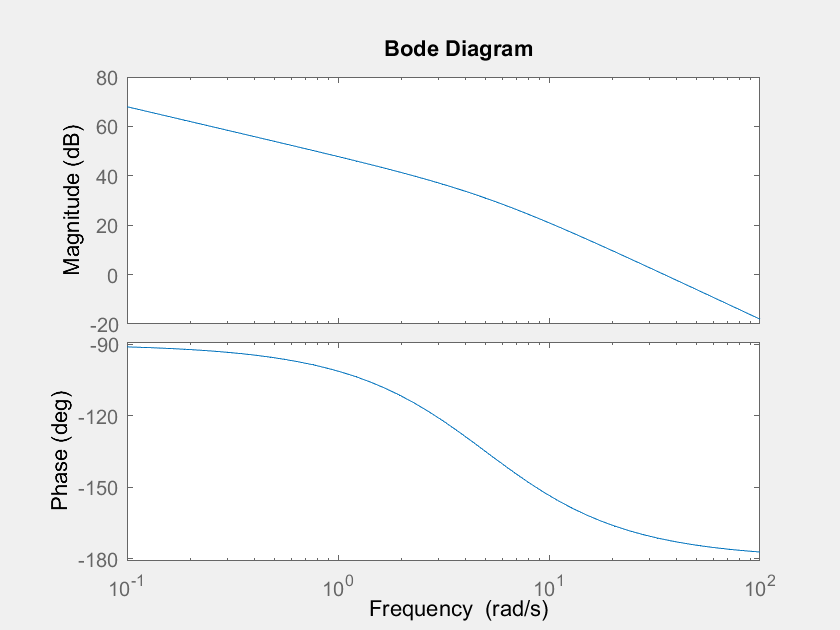


figure("Name", 'Motor DC Ejercicio 3');
set(gcf,'Visible', 'on');
bode(G3*C3)

Las características del lazo cerrado son: 

G03 = feedback(C3*G3,1); 

Respuesta al paso:

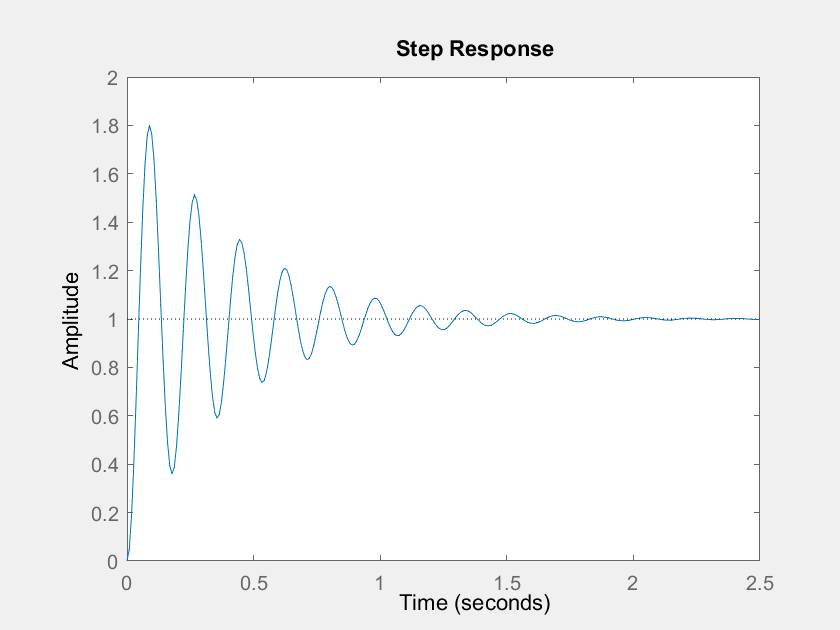

figure("Name", 'Respuesta Ante un  Paso FT Original');
set(gcf,'Visible', 'on');
step(G03); 

Respuesta ante una entrada rampa:

t3 = -5:0.01:30; 
ramp3 = ramp(t3); 
figure("Name", 'Respuesta Ante una Rampa FT Original');
set(gcf,'Visible', 'on');
response3 = lsim(G03, ramp3,t3); 

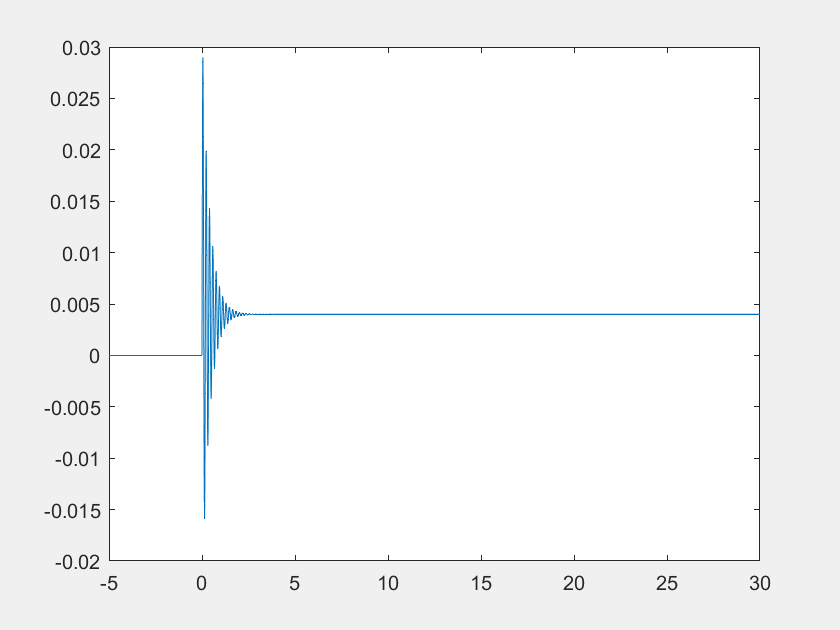

plot(t3, ramp3'-response3) 

En resumen las respuestas obtenidas son: 

- Margen de fase = 8.09°

- Sobrepico = 80%

- Error = 0.004

Teniendo en cuenta que a mayor margen de fase el sobrepico se reduce, se probará en dar solución mediante un el diseño de una red de adelanto:

campana3 = 60 - 9.04 + 10 

campana3 = 60.9600

Calculamos el parámetro "b" de la red: 

b3 = (1+sind(campana3))/(1-sind(campana3))

b3 = 14.9085

Calculamos la amplificación que genera "b": 

syms x; 
eqn = (50*kp3 / (x*sqrt((x/5)^2+1))) == 10^((-10/20)*log10(b3)); 
solution = solve(eqn,x,'Real', true); 
display(solution);

$$solution = \frac{1}{\sqrt{\frac{11831425229\,\sqrt{197121491967076347310635734816008483801241}}{25353012004564588029934064107520000}+\frac{13604595775079784137174188609}{25353012004564588029934064107520000}}}$$

wg3 = vpa(solution);
wg3 = double(wg3)

wg3 = 69.3827

Calculamos el punto donde vamos a insertar la campana: 

T3 = 1/(sqrt(b3)*wg3); 
T3 = double(T3)

T3 = 0.0037

La red de adelanto queda: 

C_adelanto3 = (1+(b3*T3*s))/(1+T3*s)

C_adelanto3 =
 
  0.05565 s + 1
  --------------
  0.003733 s + 1
 
Continuous-time transfer function.



Comprobamos los resultados obtenidos: 

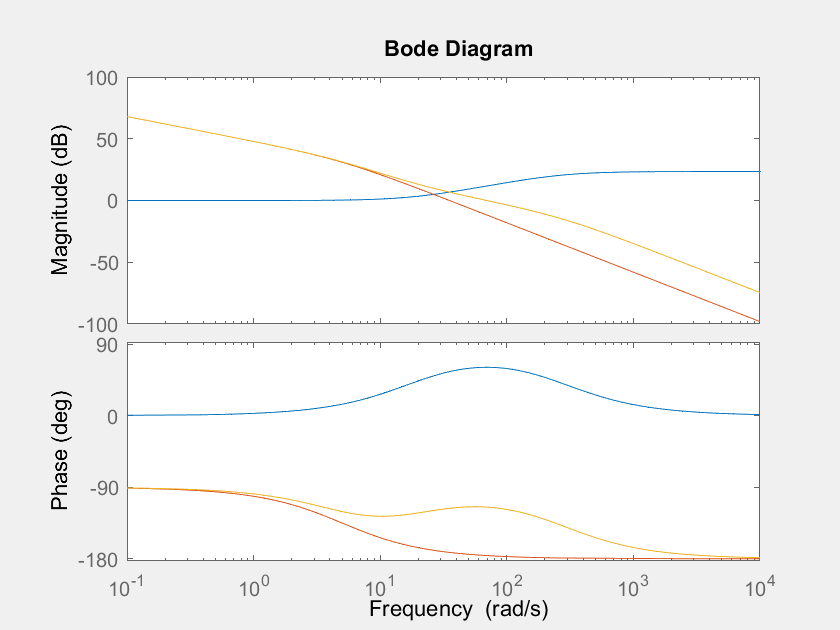

figure("Name", 'Sistema con red de adelanto Ejercicio 3 '); 
set(gcf,'Visible', 'on');
bode(C_adelanto3); 
hold on
bode(G3*C3); 
bode(C3*G3*C_adelanto3); 
hold off

La función de transferencia de lazo cerrado con la red de atraso queda: 

G003 = feedback(C_adelanto3*C3*G3,1)

G003 =
 
               69.56 s + 1250
  -----------------------------------------
  0.003733 s^3 + 1.019 s^2 + 74.56 s + 1250
 
Continuous-time transfer function.



Respuesta al paso con red de adelanto:

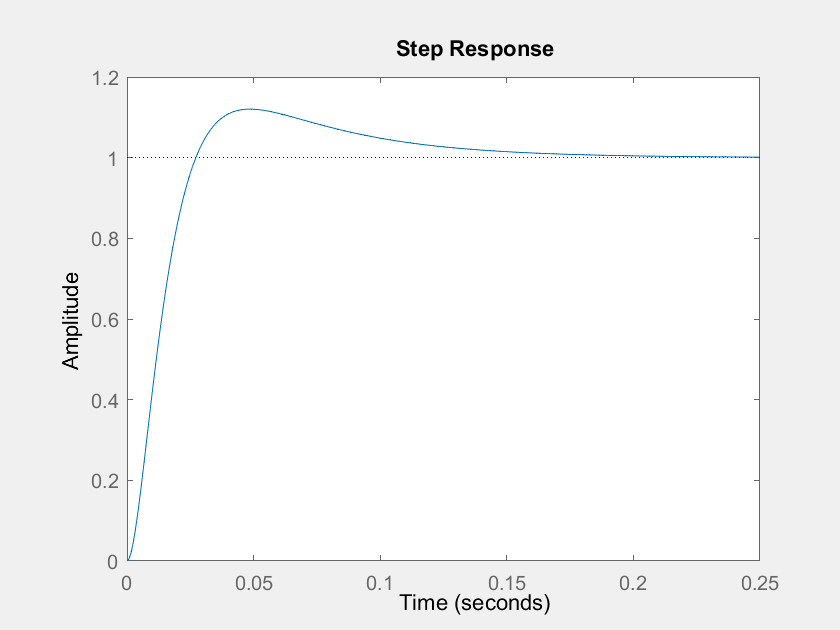

figure("Name", 'Respuesta Ante un  Paso con Red de Adelanto');
set(gcf,'Visible', 'on');
step(G003); 

Respuesta ante una entrada unitaria con red de adelanto: 

figure("Name", 'Respuesta Ante una Rampa con Red de Adelanto');
set(gcf,'Visible', 'on');
response31 = lsim(G003, ramp3,t3); 

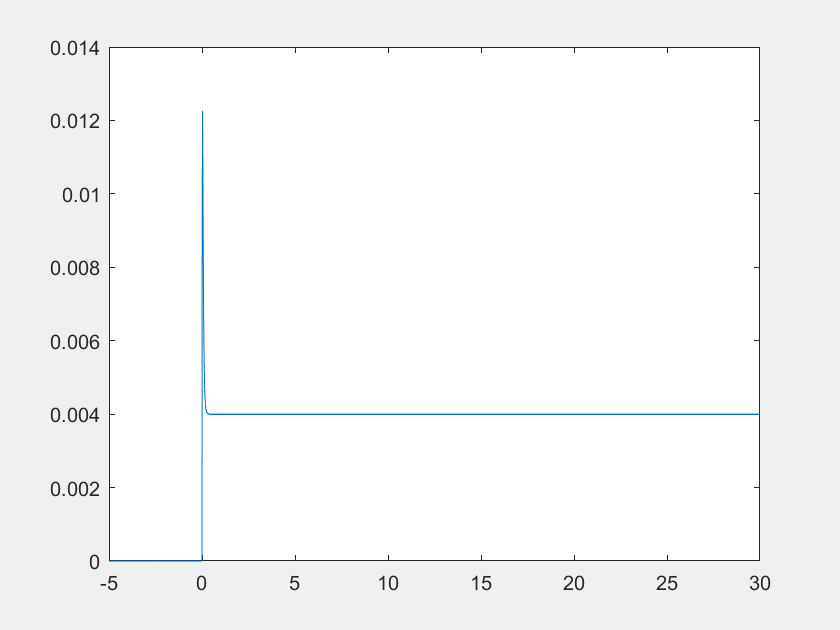

plot(t3, ramp3'-response31) 

En resumen las respuestas obtenidas con la red de adelanto son: 

- Margen de fase = 65.1°

- Sobrepico = 12%

- Error = 0.004

## Ejercicio 4: 

Considere un sistema de control tradicional con función de transferencia: 


$$G\left(s\right)=\frac{0\ldotp 05\left(s+25\right)}{s^2 \left(s^2 +0\ldotp 1s+4\right)}$$


Estabilice la amplitud del sistema utilizando compensación de adelanto para que $\textrm{GM}\ge 2\;\left(6\textrm{dB}\right)$ y $\textrm{PM}\ge 45\degree$ manteniendo el ancho de banda tan alto como sea posible.

#### Solución:

Ploteamos el BODE de la función de transferencia:

s = tf('s'); 
G4 = (0.05*(s+25))/(s^2*(s^2+0.1*s+4))

G4 =
 
      0.05 s + 1.25
  ---------------------
  s^4 + 0.1 s^3 + 4 s^2
 
Continuous-time transfer function.



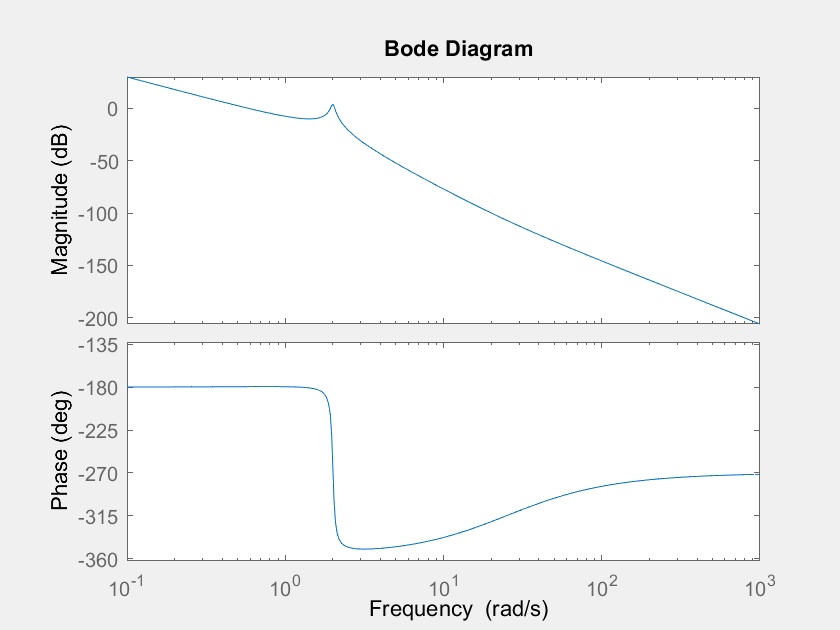

figure("Name", 'Sistema satelital Ejercicio 4');
set(gcf,'Visible', 'on');
bode(G4); 

Se observa que la pendiente en el cruce es -2 dB. Además, el pico debe mantenerse por debajo de magnitud 1 dB para evitar la posibilidad de causar una inestabilidad (estabilización de amplitud) por lo que se debe utilizar un compensador de adelanto simple: 

C_adelanto4 = (0.06 + s)/(6 + s);

Este reducirá la ganancia de baja frecuencia por un factor de 100 ya que proporcionará una pendiente de -1 dB en el cruce. Al  implementarla: 

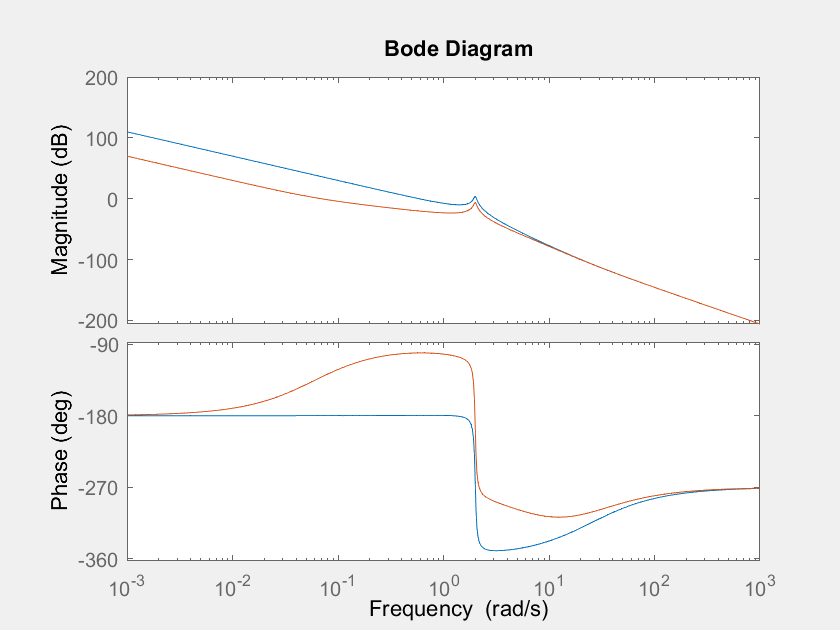

figure("Name", 'Sistema Satelital con Red de Adelanto'); 
set(gcf,'Visible', 'on');
bode(G4); 
hold on 
bode(C_adelanto4*G4); 
hold off

## Funciones Requeridas 

function [r]=ramp(t)
    r= t.*(t>=0);
end 